% Clear workspace and initialize
clear all;
close all;


Question 01.


%% Question 1: x'' + 6x' + 9x = 2e^(-3t)
disp("Question 01");

Question 01


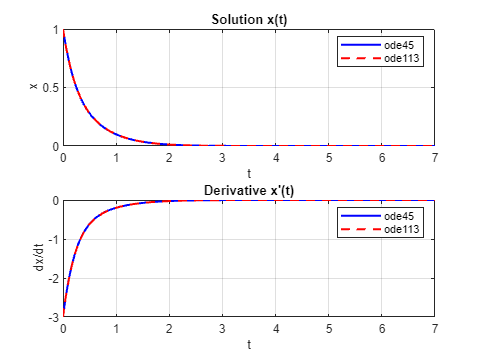


% Initial conditions: x(0) = 1, x'(0) = -3

%% Part 2: Numerical solution using ode45 and ode113
% Set up time span and initial conditions
tspan = [0 7];
y0 = [1; -3];  % Initial conditions [x(0); x'(0)]

% Solve using ode45
[t45, y45] = ode45(@odesystem, tspan, y0);

% Solve using ode113
[t113, y113] = ode113(@odesystem, tspan, y0);

% Plot numerical solutions
figure('Name', 'Numerical Solutions Comparison')
subplot(2,1,1)
plot(t45, y45(:,1), 'b-', t113, y113(:,1), 'r--', 'LineWidth', 1.5)
grid on
title('Solution x(t)')
xlabel('t')
ylabel('x')
legend('ode45', 'ode113')

subplot(2,1,2)
plot(t45, y45(:,2), 'b-', t113, y113(:,2), 'r--', 'LineWidth', 1.5)
grid on
title('Derivative x''(t)')
xlabel('t')
ylabel('dx/dt')
legend('ode45', 'ode113')


%% Part 3: Analytical solution using dsolve
% Solve analytically
syms x(t)
Dx = diff(x,t);
D2x = diff(x,t,2);
ode = D2x + 6*Dx + 9*x == 2*exp(-3*t);
ode

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+6\,\frac{\partial }{\partial t}x\left(t\right)+9\,x\left(t\right)=2\,{\mathrm{e}}^{-3\,t}$$

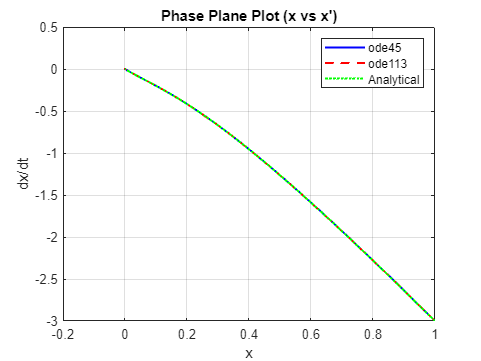

cond1 = x(0) == 1;
cond2 = Dx(0) == -3;

% Solve with initial conditions
x_sol = dsolve(ode, [cond1 cond2]);
dx_sol = diff(x_sol, t);

% Create time vector for plotting
t_anal = linspace(0, 7, 100);
x_vals = double(subs(x_sol, t, t_anal));
dx_vals = double(subs(dx_sol, t, t_anal));

% Phase plane plot (x vs x')
figure('Name', 'Phase Plane')
plot(y45(:,1), y45(:,2), 'b-', 'LineWidth', 1.5)
hold on
plot(y113(:,1), y113(:,2), 'r--', 'LineWidth', 1.5)
plot(x_vals, dx_vals, 'g:', 'LineWidth', 1.5)
grid on
title('Phase Plane Plot (x vs x'')')
xlabel('x')
ylabel('dx/dt')
legend('ode45', 'ode113', 'Analytical')
hold off


% Display analytical solution
disp('Analytical solution:')

Analytical solution:


pretty(x_sol)

            2
exp(-3 t) (t  + 1)




%% Function Definitions
% System of first-order ODEs

function dydt = odesystem(t, y)
    % Input:
    %   t - time
    %   y - state vector where y(1) = x and y(2) = x'
    % Output:
    %   dydt - derivatives [x'; x'']
    
    dydt = zeros(2,1);
    dydt(1) = y(2);                        % y1' = y2
    dydt(2) = -6*y(2) - 9*y(1) + 2*exp(-3*t);  % y2' = -6y2 - 9y1 + 2e^(-3t)
end
